# **Funktioner brugt i timerne:**

#### ***Incremental Search // Inkrementel Søgning***

*Inkrementel søgning lokaliserer et interval, hvor funktionen skifter tegn (plus til minus eller omvendt).Et af problemerne med Inkrementel søgning er stignings længden. Hvis længden er for kort tager søgning meget lang tid, hvorimod hvis spektrummet er for stort, så er der mulighed for at en rod bliver overset.*

function xb = incsearch(func,xmin,xmax,ns)
% incsearch: incremental search root locator
% xb = incsearch(func,xmin,xmax,ns):
% finds brackets of x that contain sign changes
% of a function on an interval
% input:
% func = name of function 
% xmin, xmax = endpoints of interval
% ns = number of subintervals (default = 50)
% output:
% xb(k,1) is the lower bound of the kth sign change
% xb(k,2) is the upper bound of the kth sign change
% If no brackets found, xb = [].
if nargin < 3, error('at least 3 arguments required'), end
if nargin < 4, ns = 50; end %if ns blank set to 50
% Incremental search
x = linspace(xmin,xmax,ns); 
f = func(x); 
nb = 0; xb = []; %xb is null unless sign change detected
for k = 1:length(x)−1
 if sign(f(k)) ~= sign(f(k+1)) %check for sign change
 nb = nb + 1;
 xb(nb,1) = x(k);
 xb(nb,2) = x(k+1);
 end
end
if isempty(xb) %display that no brackets were found
 disp('no brackets found')
 disp('check interval or increase ns')
else
 disp('number of brackets:') %display number of brackets
 disp(nb)
end

#### ***Bisection Method // Halveringsmetoden***

*Halveringsmetoden er en anden variant af Inkrementel moteden, hvor intervallet altid er divideret med 2. Hvis funktionen skifter tegn henover intervallet, så vil dette intervals midte blive evalueret. Rodens lokation er herefter bestemt til at ligge i subintervallet, hvor tegnsskiftet lå. Det ny oprettede subinterval bliver herefter det nye interval, hvor der søges efter tegn skiftet ved næste itteration - Altså på denne måde er intervallet hele tiden halveret. *

*Metoden fortsætter med at søge efter rodden til vi når den indstillede præcision for søgningen.*

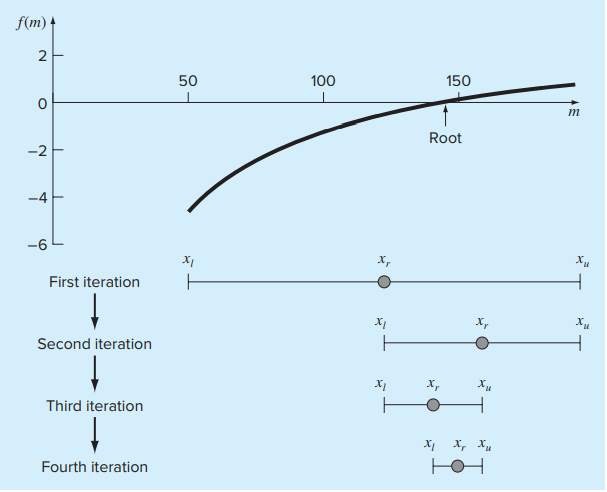

function [root,fx,ea,iter]=bisect(func,xl,xu,es,maxit,varargin)
% bisect: root location zeroes 
% [root,fx,ea,iter]=bisect(func,xl,xu,es,maxit,p1,p2,...):
% uses bisection method to find the root of func
% input:
% func = name of function 
% xl, xu = lower and upper guesses
% es = desired relative error (default = 0.0001%)
% maxit = maximum allowable iterations (default = 50)
% p1,p2,... = additional parameters used by func
% output:
% root = real root
% fx = function value at root
% ea = approximate relative error (%)
% iter = number of iterations
if nargin<3,error('at least 3 input arguments required'),end
test = func(xl,varargin{:})*func(xu,varargin{:});
if test>0,error('no sign change'),end
if nargin<4|isempty(es), es=0.0001;end
if nargin<5|isempty(maxit), maxit=50;end
iter = 0; 
xr = xl;
ea = 100;
while (1)
 xrold = xr; % Making the old estimate root the new estimate
 xr = (xl + xu)/2; % The estimate root
 iter = iter + 1;
 if xr ~= 0,ea = abs((xr − xrold)/xr) * 100;end
 test = func(xl,varargin{:})*func(xr,varargin{:});
 if test < 0
 xu = xr;
 elseif test > 0
 xl = xr;
 else
 ea = 0;
 end
 if ea <= es | iter >= maxit,break,end
end
root = xr; 
fx = func(xr, varargin{:});

#### ***Multi Bisection method // Multi halveringsmetode***

function [roots,fx,ea,iter] = multibisect(func,a,b,dx,es,maxit)
% multibisect Find flere rødder i funktion af én variabel
% Kald: [roots,fx,ea,iter] = multibisect(func,a,b,dx,es,maxit)
%   Intervallet fra a til b deles op i delintervaller af længde dx.
%   I delintervaller, hvor funktionen func skifter fortegn, antages
%   at eksistere rødder. Disse lokaliseres vha. bisektionsmetoden.
%   Hvis funktionen er kontinuert, vil alle rødder, der har en 
%   indbyrdes afstand på mindst dx, blive fundet (ekskl. dobbelt-
%   eller flerdobbeltrødder).
% Input:
%   func  = funktionen hvis rødder skal findes
%   a, b  = nedre og øvre grænse i det interval, hvor der skal søges rødder
%   dx    = længde af delintervaller (standard = (b-a)/100)
%   es    = ønsket maks. relativ fejl på rødder (standard = 0.0001%)
%   maxit = maks. iterationer med bisektionsmetoden pr. rod (standard = 50)
% Output:
%   roots = vektor med fundne rødder
%   fx    = vektor med funktionsværdier ved de fundne rodværdier
%   ea    = vektor med approksimativ relativ fejl på fundne rødder (%)
%   iter  = vektor med antal bisektionsiterationer for de fundne rødder
if nargin < 3, error('Funktionen kræver mindst tre argumenter'), end
if nargin < 4 || isempty(dx), dx = (b-a)/100; end
if nargin < 5 || isempty(es), es= 0.0001; end
if nargin < 6 || isempty(maxit), maxit= 50; end
j = 0;              % j er antal fundne rødder, der som udgangspunkt er nul
roots = [];         % Vektoren med rødder er som udgangspunkt tom
fx = [];            % Vektoren med funktionsværdier er som udgangspunkt tom
ea = [];            % Vektoren med relative fejl er som udgangspunkt tom
iter = [];          % Vektoren antal iterationer er som udgangspunkt tom
if func(a) == 0     % Hvis func(a) == 0, er a en rod
  j = j + 1;
  roots(j) = a;
  fx(j) = func(a);
  ea(j) = 0;
  iter(j) = 0;
end
n = floor((b-a)/dx); % n er antal delintervaller (floor runder ned)
xl = a;
for i = 1:n
  xu = xl + dx;
  if func(xu) == 0  % Hvis func(xu) == 0, er xu en rod
    j = j + 1;
    roots(j) = xu;
    fx(j) = func(xu);
    ea(j) = 0;
    iter(j) = 0;
  elseif func(xl)*func(xu) < 0  % Hvis fortegnsskift skal der søges en rod
    j = j + 1;
    [roots(j),fx(j),ea(j),iter(j)] = bisect(func,xl,xu,es,maxit);
  end
  xl = xu;
end
roots = roots'; 
fx = fx';
ea = ea';
iter = iter'; % Trnsp. t. søjlevektorer